 %{
ES115 Community Solar Billing Simulator (Linear + Piecewise)
 originally from Module 1: Math Foundations Team Project Bank - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-24
State the problem (Purpose):
 Electric bill costs are compared based on usage values to determine which bill would be most cost effective.

Describe input values (Knowns)and required output (Unknowns) 
    Input: - Linear and Piecewise function
          - usage range
    Output:
        - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
       - table of usage values and corresponding bills for both plans
      - intersection point where both bills cost the same
      - plan reccomendations specific to usage value of choice
     
  Engineering Workflow and Algarithems:
   - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding

MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
    -  if/else/end 
    - plot function
    - table function
    - fprintf
 %}


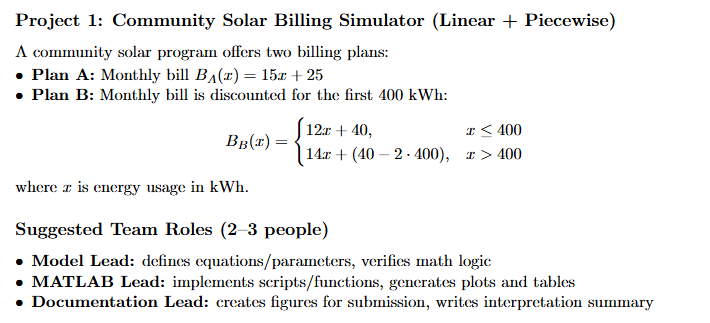

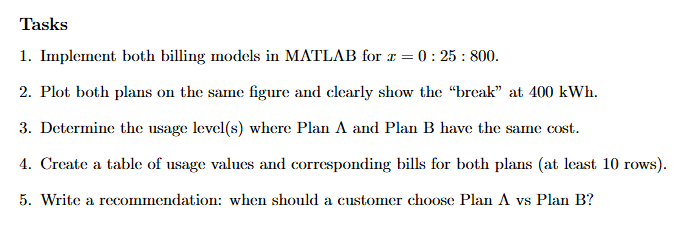

## TASK 1 : implement both billing models in MATLAB for x = 0 : 25 : 800.


clc; clear; close all; %clear workspace 

x = [0:25:800]; % establish x values (vector of numbers 0-800 going by increments of 25)

PA = 15*x + 25;   % Plan A linear function 15x+25

PB = zeros(size(x))   % Plan B array set up

PB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%plan B piecewise set up using if/else
for a = 1:length(x)  
    if x(a) <= 400
        PB(a) = 12*x(a) + 40 % plan b first section (up to 400 kwh)
    else 

PB(a) = 14*x(a) + (40 - 2 * 400); %plan b second section (above 400 kwh)
    end
end 

PB =     40     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


PB =     40   340     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


PB =     40   340   640     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


PB =     40   340   640   940     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


PB =           40         340         640         940        1240           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340        3640           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340        3640        3940           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340        3640        3940        4240           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340        3640        3940        4240        4540           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340        3640        3940        4240        4540        4840           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


## TASK 2 : plot both plans on the same figure and clearly show the “break” at 400 kWh.

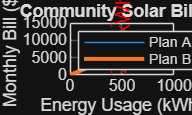


figure;
plot(x, PA, 'LineWidth', 0.5); hold on;  %plot plan A on graph (line width 0.5, no specific line color or style)
plot(x, PB, 'LineWidth', 2); %plot plan B on graph (line width 2, no specific line color or style)

%plot break at 400 kWh (red Vertical dashed line at 400 kwh)
xline(400,'--k','Label','400 kWh break','Color','red','LabelVerticalAlignment','bottom') 

%labels extablished for graph created
xlabel('Energy Usage (kWh)');  %label graphs horizontal axis (energy usage)
ylabel('Monthly Bill ($)');  %Label graphs vertical axis (monthly bill cost)
title('Community Solar Billing'); %establish graph title 
legend('Plan A', 'Plan B', 'Location','northwest'); grid on; %create legend for graph and specifiy location (top left corner)

## TASK 3: Determine the usage level(s) where Plan A and Plan B have the same cost.

% find Plan A and B intersection
intersec1 = (40-25)/(15-12); % x=5 (valid solution)      %determine first intersection point for PLAN A&B
intersec2 = -785/5; %invalid soultion            % determine second intersection point PLAN A&B

%display text reflecting results found below graph
fprintf('Plan A & B have the same cost at x=%.2f kWh (only valid solution).\n',intersec1); 

Plan A & B have the same cost at x=5.00 kWh (only valid solution).


## Task 4: Create a table of usage values and corresponding bills for both plans (at least 10 rows).


UseV = (0:80:800)'; %define usage values with division of minimum 10 rows (vector of numbers 0-800 going by increments of 80)
PAV = 15*UseV + 25; % Plan A bill established using linear equation 


PBV = zeros(size(UseV)); %Plan B array redefined

for a = 1:length(UseV)
    if UseV(a) <= 400
        PBV(a) = 12*UseV(a) + 40; %Plan B bill established using piecewise function(usage up to 400 kwh)
    else
        PBV(a) = 14*UseV(a) - 760; %Plan B bill established using piecewise function(usage above 400 kwh)
    end
end


BillingTable = table(UseV, PAV, PBV, ...         %create table with usage values and resulting billing costs for each plan
    'VariableNames', {'Usage(kWh)','PlanA Bill','PlanB Bill'})      %define and label variables used in table 

BillingTable = 11×3 table
    Usage(kWh)    PlanA Bill    PlanB Bill
    __________    __________    __________

         0             25            40   
        80           1225          1000   
       160           2425          1960   
       240           3625          2920   
       320           4825          3880   
       400           6025          4840   
       480           7225          5960   
       560           8425          7080   
       640           9625          8200   
       720          10825          9320   
       800          12025         10440   


## Task 5: Write a recommendation: when should a customer choose Plan A vs Plan B?

% reccommendation
fprintf(['RECCOMMENDATIONS!\n'])  %Display reccomendations title

RECCOMMENDATIONS!


fprintf(['- Plan A appears to be the best and cheapest option for low energy usages (0-5 kwh) \n']) %Plan B is most cost effective for those who will used about 0-5 kwh of energy

- Plan A appears to be the best and cheapest option for low energy usages (0-5 kwh) 


fprintf(['- for energy usage above 5 kWh, Plan B is the best option, that includes at and above 400 kwh.\n']) %otherwise, Plan A appears to be the best option for all energy usage above 5 kwh

- for energy usage above 5 kWh, Plan B is the best option, that includes at and above 400 kwh.


%{ 
Reflection After Completing the Project:
- What do slope and intercept represent for each plan?
  The intercept of plan A represents the initial service cost of $25 while
  the slope is reflective of the cost rate of $15/kwh. Similarly, the
  intercept of plan B's first section reflects an initial customer charge
  of $40 and its slope is the cost increase at a rate of $12/kwh. Plan b's
  second region slope represents the cost increase rate of $14/kwh with an
  intercept that showcases the adjustment in customer charge in order to
  continue service after 400 kwh. 

- How does the piecewise structure change decision-making?
The piecewise structure affects decision making as customers are able to
benefit from the discounted offer with energy usage at 400 kwh and below. 

- What did you learn?
 Throughout my completion of this project, I was able to work on and
    add to the many tools and techniques that matlab has to offer. Going
    into this course matlab was an unfamilar resource to me and despite all
    of the research that had went into the weeks prior for preperatio of
    thius project, I still felt somewhat unprepared. Despite that, this
    project has allowed me to test different functions that I haven't been
    able to throuroughly utilize in the past such as, fprintf, table
    functions, intersection values on a graph, etc. 
 
  - What could be done differently?
many features among this project couldv'e been done differently such as including a user input system, testing more functions, etc. 
   
- Rate the project (1 - 10) (1 - represents simple and 10 represents difficult) 
   Rate : 6 
The most difficult thing about these projects is knowing where to begin,
especially when you are extremely unfamilar with the technology at hand.
However, the use of if/else statements allowed me to power through what I
felt was the most difficult section of this project.
%}